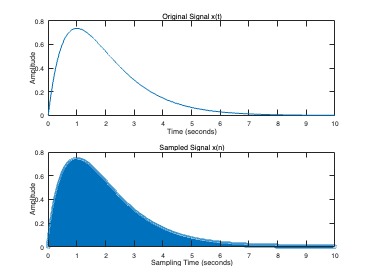

% Homework #2 - Practicing Shannon (from [10])

% Task 1 - Sampling x(t) = 2te^{-t} with Ts = 0.005
% Define the signal x(t) = 2t * e^(-t)
t = 0:0.001:10; % Define a continuous time range from 0 to 10 seconds with a 0.001-second interval
x_t = 2 * t .* exp(-t); % Calculate the signal values

% Define the sampling period Ts = 0.005 seconds
Ts = 0.005;
% Perform sampling
n = 0:Ts:10; % Sampling time range
x_n = 2 * n .* exp(-n); % Sample the signal
% Perform frequency analysis
Fs = 1 / Ts; % Sampling frequency
N = length(x_n); % Number of samples
X_n = fft(x_n, N); % Apply Fast Fourier Transform (FFT) to the sampled signal
% Calculate the frequency spectrum
f = (-Fs/2):(Fs/N):(Fs/2-Fs/N); % Frequency range
X_n = fftshift(X_n); % Center the spectrum
% Plot the original signal and the sampled signal
figure;
subplot(2,1,1);
plot(t, x_t);
title('Original Signal x(t)');
xlabel('Time (seconds)');
ylabel('Amplitude');
subplot(2,1,2);
stem(n, x_n);
title('Sampled Signal x(n)');
xlabel('Sampling Time (seconds)');
ylabel('Amplitude');

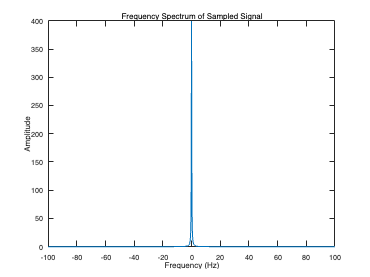

% Plot the frequency spectrum
figure;
plot(f, abs(X_n));
title('Frequency Spectrum of Sampled Signal');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

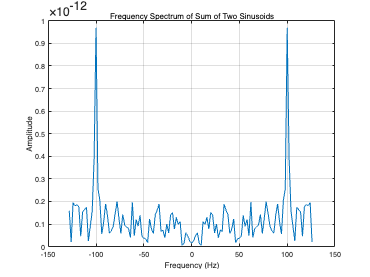


% Task 2.1 - Generating a signal from the sum of two sinusoids at 100 Hz and 156 Hz
% Define the signal parameters
duration = 0.5; % Duration of the signal in seconds
Fs = 256; % Sampling frequency in Hz
t = 0:1/Fs:duration-1/Fs; % Time vector

% Define the frequencies and amplitudes of the sinusoids
freq1 = 100; % Frequency of the first sinusoid in Hz
freq2 = 156; % Frequency of the second sinusoid in Hz
amplitude = 1; % Amplitude of both sinusoids in volts

% Generate the sinusoidal signals
signal1 = amplitude * sin(2 * pi * freq1 * t);
signal2 = amplitude * sin(2 * pi * freq2 * t);

% Sum the two sinusoidal signals
sum_signal = signal1 + signal2;

% Compute the FFT of the signal
N = length(sum_signal);
frequencies = Fs * (-N/2:N/2-1) / N;
fft_result = fftshift(fft(sum_signal, N));

% Plot the frequency spectrum
figure;
plot(frequencies, abs(fft_result));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum of Sum of Two Sinusoids');
grid on;

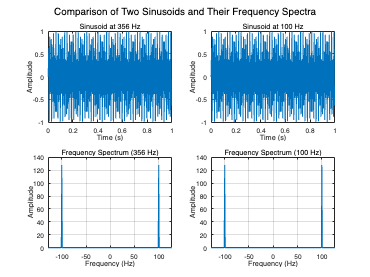


% Task 2.2 - Generating and plotting a sinusoid of 356 Hz sampled at 256 Hz
% Define the signal parameters
duration = 1; % Duration of the signals in seconds
Fs = 256; % Sampling frequency in Hz
t = 0:1/Fs:duration-1/Fs; % Time vector

% Define the frequencies of the sinusoids
freq1 = 356; % Frequency of the first sinusoid in Hz
freq2 = 100; % Frequency of the second sinusoid in Hz

% Generate the sinusoidal signals
signal1 = sin(2 * pi * freq1 * t);
signal2 = sin(2 * pi * freq2 * t);

% Compute the FFT of the first signal (356 Hz)
N1 = length(signal1);
frequencies1 = Fs * (-N1/2:N1/2-1) / N1;
fft_result1 = fftshift(fft(signal1, N1));

% Compute the FFT of the second signal (100 Hz)
N2 = length(signal2);
frequencies2 = Fs * (-N2/2:N2/2-1) / N2;
fft_result2 = fftshift(fft(signal2, N2));

% Plot the first signal (356 Hz) and its frequency spectrum
figure;
subplot(2,2,1);
plot(t, signal1);
xlabel('Time (s)');
ylabel('Amplitude');
title('Sinusoid at 356 Hz');
grid on;

subplot(2,2,3);
plot(frequencies1, abs(fft_result1));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum (356 Hz)');
grid on;

% Plot the second signal (100 Hz) and its frequency spectrum
subplot(2,2,2);
plot(t, signal2);
xlabel('Time (s)');
ylabel('Amplitude');
title('Sinusoid at 100 Hz');
grid on;

subplot(2,2,4);
plot(frequencies2, abs(fft_result2));
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Frequency Spectrum (100 Hz)');
grid on;

% Adjust the subplot spacing
sgtitle('Comparison of Two Sinusoids and Their Frequency Spectra');


% Le repliement spectral est le processus par lequel les composantes de fréquence sont replacées à d'autres endroits du spectrogramme lorsque la fréquence d'échantillonnage est insuffisante pour capturer les composantes de haute fréquence du signal. Voici une description concluante du repliement spectral :
% Le repliement spectral se produit lorsque la fréquence d'échantillonnage est insuffisante : le repliement spectral est un phénomène qui se produit lorsque la fréquence d'échantillonnage est inférieure à deux fois la composante de fréquence la plus élevée du signal.
% Alias spectral : dans les spectrogrammes, l'alias spectral se manifeste par la projection des composantes à haute fréquence du signal dans la région à basse fréquence du spectre, ce qui entraîne l'apparition de composantes de fréquence incorrectes dans le spectrogramme.
% Solution pour le repliement spectral : pour éviter le repliement spectral, il est généralement nécessaire d'augmenter la fréquence d'échantillonnage afin de garantir que toutes les composantes de fréquence du signal puissent être capturées avec précision. Une autre solution consiste à utiliser un filtre passe-bas après l'échantillonnage du signal pour éliminer les composantes supérieures à la fréquence de Nyquist.
% Effets du repliement spectral : le repliement spectral peut entraîner des erreurs d'interprétation et des distorsions dans l'analyse des signaux, car les composantes à haute fréquence peuvent être mélangées aux composantes à basse fréquence, ce qui rend les caractéristiques de fréquence difficiles à interpréter et à identifier.
% Par conséquent, pour garantir la précision de l'échantillonnage du signal et de l'analyse du spectre, la fréquence d'échantillonnage appropriée doit être soigneusement sélectionnée afin d'éviter le repliement spectral.


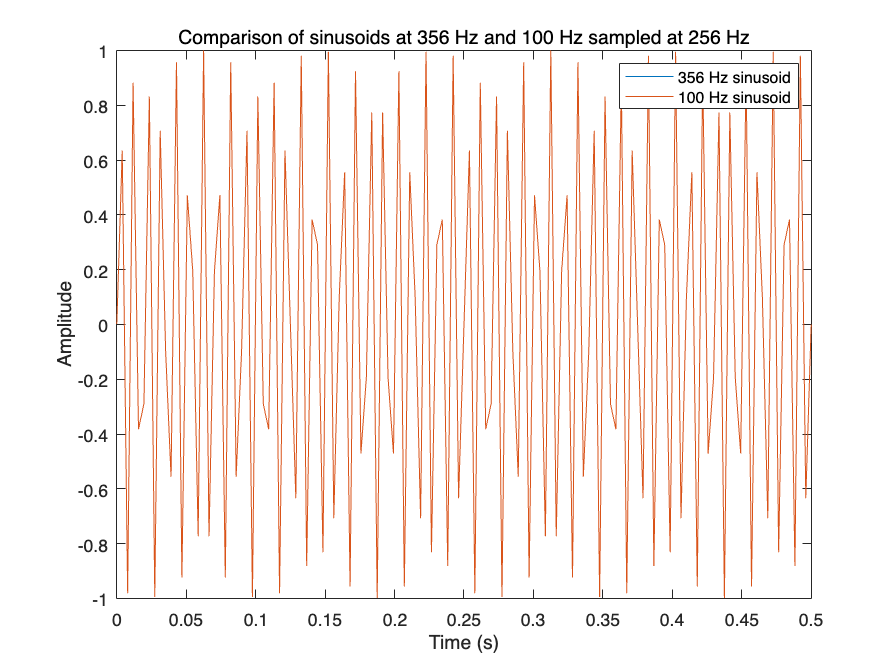


% Comparing with a sinusoid of 100 Hz
y3 = sin(2*pi*f1*t); % Sinusoid at 100 Hz
figure;
plot(t, y2, t, y3);
legend('356 Hz sinusoid','100 Hz sinusoid');
title('Comparison of sinusoids at 356 Hz and 100 Hz sampled at 256 Hz');
xlabel('Time (s)');
ylabel('Amplitude');